clc
clear
close all
syms s kp ki kd

%% 1. Definir la Función de Transferencia del Sistema Térmico
numTF = [0.011]

numTF = 0.0110

denTF = [1 0.2556 0.005556]

denTF =     1.0000    0.2556    0.0056


TF = tf(numTF, denTF)

TF =
 
            0.011
  -------------------------
  s^2 + 0.2556 s + 0.005556
 
Continuous-time transfer function.
Model Properties



%% 2. Parámetros del Control PID
TS = 150

TS = 150

mp = 0.03

mp = 0.0300

zita = sqrt((log(mp)^2) / (pi^2 + log(mp)^2))

zita = 0.7448

wn = 4/(zita*TS)

wn = 0.0358

b = 10

b = 10

EXPO_CONTI = 1

EXPO_CONTI = 1


% Polinomio característico deseado
PD = (s^2 + 2*zita*wn*s + wn^2) * (s + b*zita*wn)^EXPO_CONTI

$$PD = \left(s+\frac{4}{15}\right)\,\left(s^{2}+\frac{4\,s}{75}+\frac{2955859157952571}{2305843009213693952}\right)$$


% Control PID
numC = (kd*s^2) + (kp*s) + ki

$$numC = \mathrm{kd}\,s^{2}+\mathrm{kp}\,s+\mathrm{ki}$$

denC = s

$$denC = s$$

pLC = collect(poly2sym(denTF,s)*denC + poly2sym(numTF,s)*numC, s);
coeffi_LC = fliplr(coeffs(pLC, s))

$$coeffi\_LC = \left(\begin{array}{cccc} 1 & \frac{11\,\mathrm{kd}}{1000}+\frac{639}{2500} & \frac{11\,\mathrm{kp}}{1000}+\frac{3202815939797821}{576460752303423488} & \frac{11\,\mathrm{ki}}{1000} \end{array}\right)$$


PD = vpa(collect(PD), 4)

$$PD = s^{3}+0.32\,s^{2}+0.0155\,s+0.0003418$$

coeffi_PD = double(fliplr(coeffs(PD)))

coeffi_PD =     1.0000    0.3200    0.0155    0.0003



% Resolver ecuaciones para obtener KP, KI, KD
eqns = coeffi_LC(1,[2:end])./coeffi_LC(1,1) == coeffi_PD(1,[2:end])

$$eqns = \left(\begin{array}{ccc} \frac{11\,\mathrm{kd}}{1000}+\frac{639}{2500}=\frac{43980465111}{137438953472} & \frac{11\,\mathrm{kp}}{1000}+\frac{3202815939797821}{576460752303423488}=\frac{272751394993}{17592186044416} & \frac{11\,\mathrm{ki}}{1000}=\frac{384877494525}{1125899906842624} \end{array}\right)$$

soluc = solve(eqns);
KP = double(vpa(soluc.kp, 3))

KP = 0.9044

KI = double(vpa(soluc.ki, 3))

KI = 0.0311

KD = double(vpa(soluc.kd, 3))

KD = 5.8545


% Controlador PID
GC = pid(KP, KI, KD)

GC =
 
             1          
  Kp + Ki * --- + Kd * s
             s          

  with Kp = 0.904, Ki = 0.0311, Kd = 5.85
 
Continuous-time PID controller in parallel form.
Model Properties


GC1 = feedback(GC * TF, 1)

GC1 =
 
   0.0644 s^2 + 0.009948 s + 0.0003418
  -------------------------------------
  s^3 + 0.32 s^2 + 0.0155 s + 0.0003418
 
Continuous-time transfer function.
Model Properties



% Simulación del control PID
t = 0:1:1000;
[y_PID, t_PID] = step(GC1, t);

%% 3. Generar Datos para Entrenar la Red Neuronal
error = 1 - y_PID;                 % Error del sistema
derivada_error = [0; diff(error)]   % Derivada del error

derivada_error =          0
   -0.0595
   -0.0512
   -0.0448
   -0.0398
   -0.0358
   -0.0327
   -0.0303
   -0.0283
   -0.0267


integral_error = cumsum(error) * 0.01 % Integral del error

integral_error =     0.0100
    0.0194
    0.0283
    0.0367
    0.0448
    0.0525
    0.0598
    0.0669
    0.0737
    0.0802



X_train = [error'; derivada_error'; integral_error'] % Entradas a la red

X_train =     1.0000    0.9405    0.8893    0.8445    0.8047    0.7689    0.7362    0.7059    0.6776    0.6509    0.6255    0.6013    0.5780    0.5555    0.5338    0.5127    0.4922    0.4723    0.4529    0.4341    0.4157    0.3978    0.3804    0.3634    0.3469    0.3308    0.3151    0.2999    0.2851    0.2707    0.2567    0.2432    0.2300    0.2172    0.2049    0.1929    0.1813    0.1700    0.1592    0.1487    0.1386    0.1288    0.1194    0.1103    0.1015    0.0931    0.0850    0.0772    0.0697    0.0625
         0   -0.0595   -0.0512   -0.0448   -0.0398   -0.0358   -0.0327   -0.0303   -0.0283   -0.0267   -0.0254   -0.0243   -0.0233   -0.0225   -0.0217   -0.0211   -0.0205   -0.0199   -0.0194   -0.0189   -0.0184   -0.0179   -0.0174   -0.0170   -0.0165   -0.0161   -0.0157   -0.0152   -0.0148   -0.0144   -0.0140   -0.0136   -0.0132   -0.0128   -0.0124   -0.0120   -0.0116   -0.0112   -0.0109   -0.0105   -0.0101   -0.0098   -0.0094   -0.0091   -0.0088   -0.0084   -0.0081   -0.0078   -0.007

Y_train = y_PID';  % Salida esperada (respuesta del PID)

%% 4. Ajustes en la Red Neuronal
% Modificando la arquitectura de la red (más neuronas y más capas)
net = feedforwardnet([50 50 50])  % Tres capas ocultas con 50 neuronas cada una

net =

    Neural Network
 
              name: 'Feed-Forward Neural Network'
          userdata: (your custom info)
 
    dimensions:
 
         numInputs: 1
         numLayers: 4
        numOutputs: 1
    numInputDelays: 0
    numLayerDelays: 0
 numFeedbackDelays: 0
 numWeightElements: 5150
        sampleTime: 1
 
    connections:
 
       biasConnect: [1; 1; 1; 1]
      i

net.trainParam.epochs = 5000  % Aumentar el número de épocas para mayor entrenamiento

net =

    Neural Network
 
              name: 'Feed-Forward Neural Network'
          userdata: (your custom info)
 
    dimensions:
 
         numInputs: 1
         numLayers: 4
        numOutputs: 1
    numInputDelays: 0
    numLayerDelays: 0
 numFeedbackDelays: 0
 numWeightElements: 5150
        sampleTime: 1
 
    connections:
 
       biasConnect: [1; 1; 1; 1]
      i

net.trainParam.show = 100      % Mostrar resultados cada 100 épocas

net =

    Neural Network
 
              name: 'Feed-Forward Neural Network'
          userdata: (your custom info)
 
    dimensions:
 
         numInputs: 1
         numLayers: 4
        numOutputs: 1
    numInputDelays: 0
    numLayerDelays: 0
 numFeedbackDelays: 0
 numWeightElements: 5150
        sampleTime: 1
 
    connections:
 
       biasConnect: [1; 1; 1; 1]
      i

net.trainParam.goal = 1e-6    % Establecer la meta de error

net =

    Neural Network
 
              name: 'Feed-Forward Neural Network'
          userdata: (your custom info)
 
    dimensions:
 
         numInputs: 1
         numLayers: 4
        numOutputs: 1
    numInputDelays: 0
    numLayerDelays: 0
 numFeedbackDelays: 0
 numWeightElements: 5150
        sampleTime: 1
 
    connections:
 
       biasConnect: [1; 1; 1; 1]
      i

net.trainParam.lr = 0.01      % Ajustar la tasa de aprendizaje

net =

    Neural Network
 
              name: 'Feed-Forward Neural Network'
          userdata: (your custom info)
 
    dimensions:
 
         numInputs: 1
         numLayers: 4
        numOutputs: 1
    numInputDelays: 0
    numLayerDelays: 0
 numFeedbackDelays: 0
 numWeightElements: 5150
        sampleTime: 1
 
    connections:
 
       biasConnect: [1; 1; 1; 1]
      i


% Ajuste de normalización (sin valores excesivos)
[X_train_norm, X_train_ps] = mapminmax(X_train, 0, 1) % Normalizar datos de entrada

X_train_norm =     1.0000    0.9434    0.8946    0.8520    0.8142    0.7801    0.7489    0.7201    0.6932    0.6678    0.6436    0.6205    0.5984    0.5770    0.5563    0.5362    0.5168    0.4978    0.4794    0.4614    0.4440    0.4269    0.4103    0.3942    0.3785    0.3631    0.3482    0.3337    0.3197    0.3060    0.2927    0.2798    0.2672    0.2551    0.2433    0.2319    0.2209    0.2102    0.1998    0.1899    0.1802    0.1709    0.1619    0.1533    0.1450    0.1369    0.1292    0.1218    0.1147    0.1079
    0.9867         0    0.1375    0.2441    0.3272    0.3923    0.4437    0.4845    0.5173    0.5440    0.5660    0.5845    0.6003    0.6140    0.6262    0.6372    0.6472    0.6566    0.6655    0.6739    0.6820    0.6899    0.6976    0.7051    0.7125    0.7198    0.7270    0.7341    0.7411    0.7480    0.7549    0.7617    0.7684    0.7750    0.7815    0.7879    0.7943    0.8005    0.8067    0.8127    0.8187    0.8245    0.8303    0.8359    0.8415    0.8469    0.8523    0.8575    

X_train_ps = struct with fields:
         name: 'mapminmax'
        xrows: 3
         xmax: [3×1 double]
         xmin: [3×1 double]
       xrange: [3×1 double]
        yrows: 3
         ymax: 1
         ymin: 0
       yrange: 1
         gain: [3×1 double]
      xoffset: [3×1 double]
    no_change: 0


[Y_train_norm, Y_train_ps] = mapminmax(Y_train, 0, 1) % Normalizar datos de salida

Y_train_norm =          0    0.0566    0.1054    0.1480    0.1858    0.2199    0.2511    0.2799    0.3068    0.3322    0.3564    0.3795    0.4016    0.4230    0.4437    0.4638    0.4832    0.5022    0.5206    0.5386    0.5560    0.5731    0.5897    0.6058    0.6215    0.6369    0.6518    0.6663    0.6803    0.6940    0.7073    0.7202    0.7328    0.7449    0.7567    0.7681    0.7791    0.7898    0.8002    0.8101    0.8198    0.8291    0.8381    0.8467    0.8550    0.8631    0.8708    0.8782    0.8853    0.8921


Y_train_ps = struct with fields:
         name: 'mapminmax'
        xrows: 1
         xmax: 1.0508
         xmin: 0
       xrange: 1.0508
        yrows: 1
         ymax: 1
         ymin: 0
       yrange: 1
         gain: 0.9516
      xoffset: 0
    no_change: 0


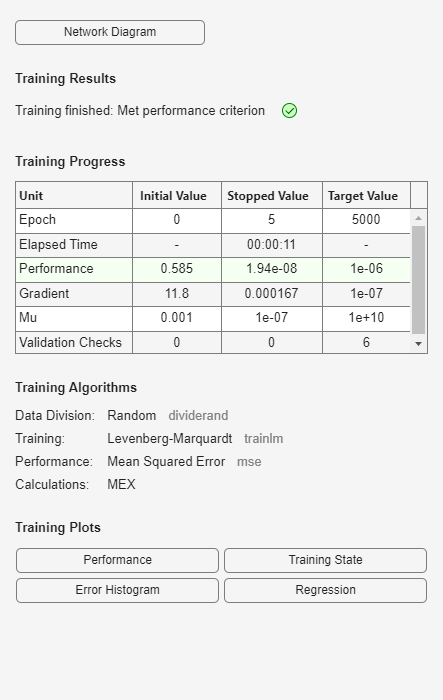

net =

    Neural Network
 
              name: 'Feed-Forward Neural Network'
          userdata: (your custom info)
 
    dimensions:
 
         numInputs: 1
         numLayers: 4
        numOutputs: 1
    numInputDelays: 0
    numLayerDelays: 0
 numFeedbackDelays: 0
 numWeightElements: 5351
        sampleTime: 1
 
    connections:
 
       biasConnect: [1; 1; 1; 1]
      i


% Entrenar la red neuronal
net = train(net, X_train_norm, Y_train_norm)


%% 5. Aplicar la Red Neuronal
y_neural = net(X_train_norm)

y_neural =    -0.0001    0.0563    0.0796    0.1475    0.2173    0.2303    0.2505    0.2792    0.3068    0.3321    0.3562    0.3796    0.4012    0.4223    0.4430    0.4631    0.4825    0.5013    0.5197    0.5379    0.5557    0.5725    0.5888    0.6048    0.6208    0.6366    0.6517    0.6660    0.6799    0.6936    0.7072    0.7203    0.7329    0.7450    0.7565    0.7677    0.7787    0.7896    0.8003    0.8106    0.8206    0.8301    0.8392    0.8479    0.8561    0.8640    0.8715    0.8788    0.8858    0.8925



% Desnormalizar la salida
y_neural = mapminmax('reverse', y_neural, Y_train_ps)

y_neural =    -0.0001    0.0592    0.0837    0.1550    0.2283    0.2420    0.2632    0.2934    0.3224    0.3490    0.3743    0.3989    0.4216    0.4438    0.4655    0.4866    0.5071    0.5268    0.5461    0.5653    0.5839    0.6016    0.6187    0.6355    0.6523    0.6689    0.6848    0.6999    0.7144    0.7289    0.7431    0.7569    0.7702    0.7828    0.7949    0.8067    0.8183    0.8297    0.8409    0.8518    0.8623    0.8723    0.8819    0.8909    0.8996    0.9079    0.9158    0.9234    0.9308    0.9378


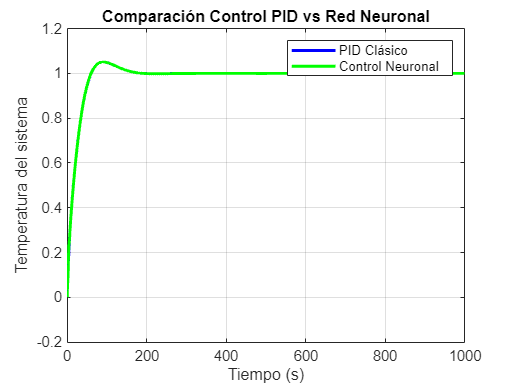


%% 6. Comparación de Respuestas
figure
plot(t_PID, y_PID, 'b', 'LineWidth', 2)   % Respuesta PID clásica
hold on
plot(t_PID, y_neural, 'g', 'LineWidth', 2)  % Respuesta control neuronal
legend('PID Clásico', 'Control Neuronal')
xlabel('Tiempo (s)')
ylabel('Temperatura del sistema')
title('Comparación Control PID vs Red Neuronal')
grid on


%% 7. Exportar a Simulink (Opcional)
gensim(net)

ans = 'untitled'